AMY_st.name='AMY'; 
AMY_st.lat=36.5383338928;
AMY_st.lon=126.3300018311;
AMY_st.alt=46;
AMY_st.env='coast';
AMY_st.footp='RB';


AMY_rdV1=read_betsy('amy_2008_2017',AMY_st.name);

AMY_rd=read_betsy('amy_2008_2018',AMY_st.name);

datevec(AMY_rd.Time(1))

ans =         2008           1           2           0           0           0


datevec(AMY_rd.Time(end))

ans =         2019           1           1           0           0           0


prctile(AMY_rd.U_S11,[5 50 95])

ans =     8.2650   26.1000   65.9000


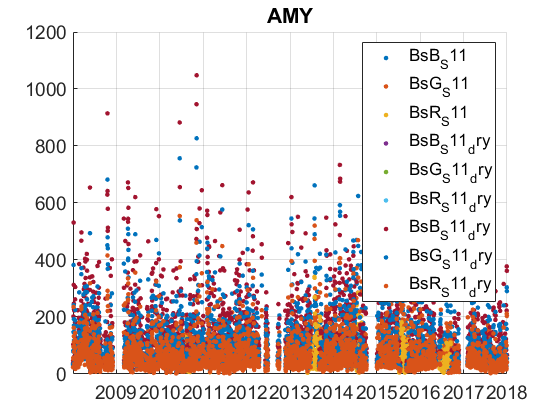

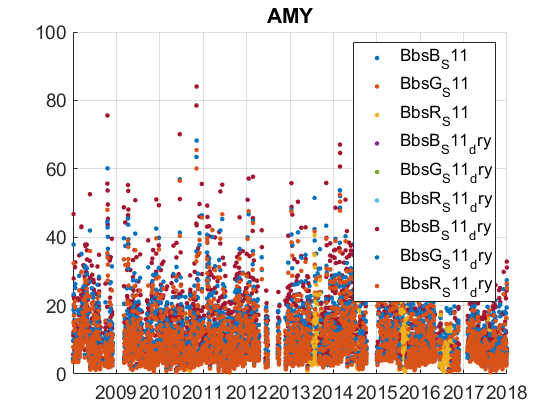

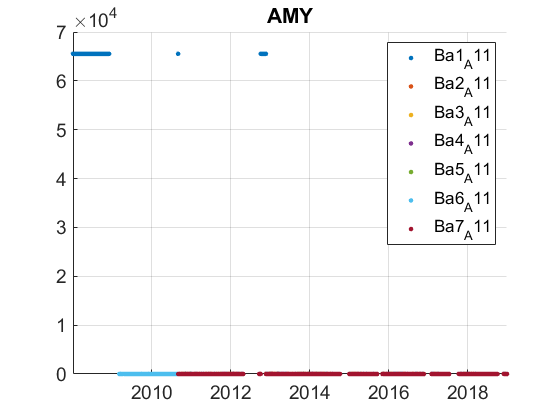

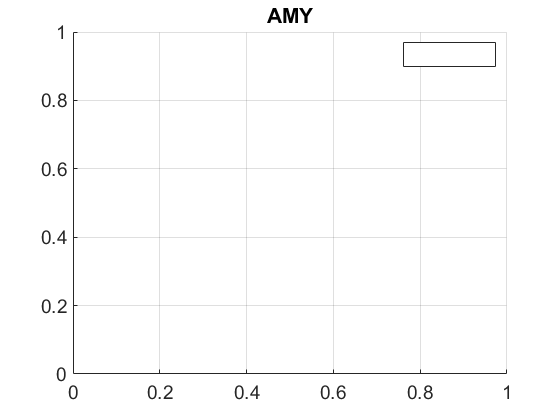

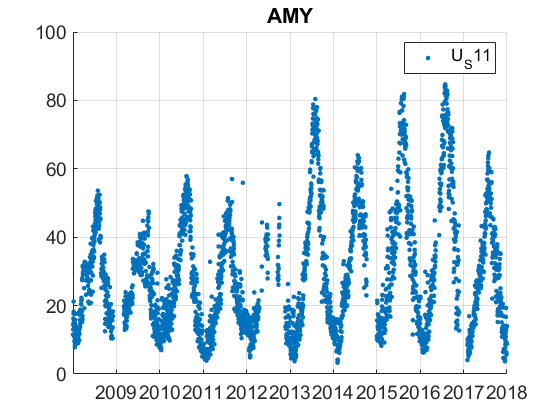

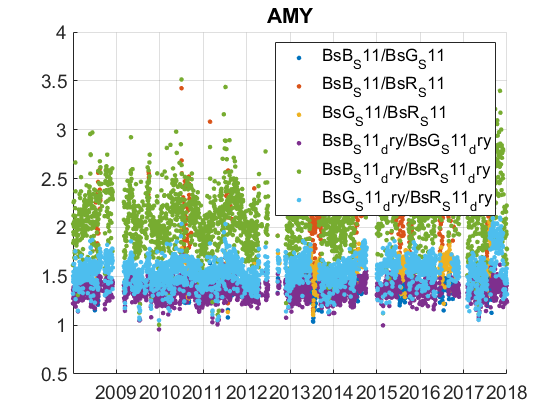

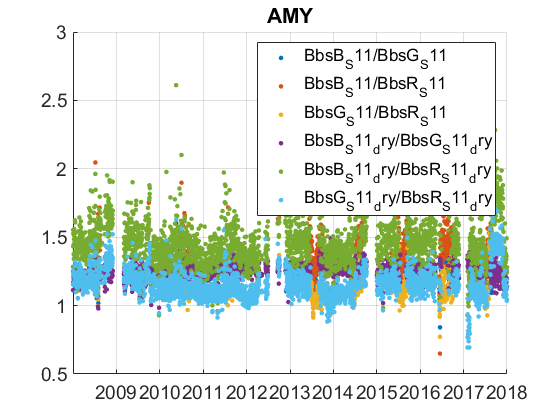

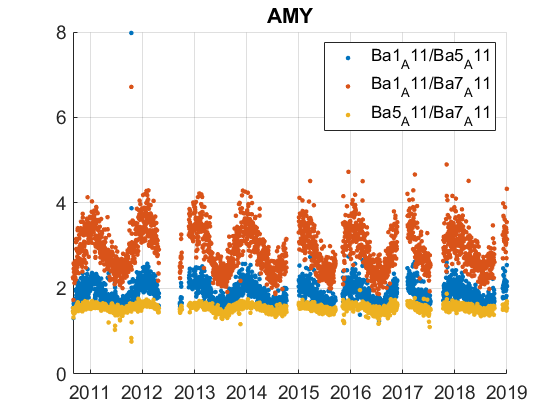


plotFigControl(AMY_rd,AMY_st.name);

% one size cut, ok
% sc: ok, no negatives, no clear seasonal cycle
%Abs exponent: clear seasonal cycle but no seasonal cycle in abs.

sc18=read_nasa_ames('KR0100R.20180101000000.20190807000000.nephelometer..pm10.1y.1h.KR04L_TSI_3563_2009.KR04L_scat_coef.lev2.nas',['\\meteoswiss.ch\mch\pay-prod\Aerosol_actris_trend\data\amy\']);
t=datenum([2018 01 01 00 00 00])*ones(8760,1)+sc18.starttime;
sc18x=timetable(datetime (datevec(t)));
sc18x.BsB=sc18.aerosol_light_scattering_coefficient;
sc18x.BsG=sc18.aerosol_light_scattering_coefficient15;
sc18x.BsR=sc18.aerosol_light_scattering_coefficient18;
sc18x.BbsB=sc18.aerosol_light_backscattering_coefficient;
sc18x.BbsG=sc18.aerosol_light_backscattering_coefficient6;
sc18x.BbsR=sc18.aerosol_light_backscattering_coefficient9;
indF=sc18.flag>0.798 | ismember(sc18.flag,Invalid_flag./1000);
namessc=fieldnames(sc18x);
c=startsWith(namessc,'B');
nsc=namessc(c);
for i=1:length(nsc)
    sc18x.(nsc{i})(indF)=NaN;
    
end
rh18=read_nasa_ames('KR0100R.20180101000000.20190807000000.nephelometer.relative_humidity.instrument.1y.1h.KR04L_TSI_3563_2009.KR04L_scat_coef.lev2.nas',['\\meteoswiss.ch\mch\pay-prod\Aerosol_actris_trend\data\amy\']);
indRH=rh18.rH>50;
sc18x.BsB_dry=sc18x.BsB;
sc18x.BsB_dry(indRH)=NaN;
sc18x.BsG_dry=sc18x.BsG;
sc18x.BsG_dry(indRH)=NaN;
sc18x.BsR_dry=sc18x.BsR;
sc18x.BsR_dry(indRH)=NaN;
sc18x.BbsB_dry=sc18x.BbsB;
sc18x.BbsB_dry(indRH)=NaN;
sc18x.BbsG_dry=sc18x.BbsG;
sc18x.BbsG_dry(indRH)=NaN;
sc18x.BbsR_dry=sc18x.BbsR;
sc18x.BbsR_dry(indRH)=NaN;
sc18x.U=rh18.rH;
sc18_d=retime(sc18x,'daily',@nanmedian);


pp=timerange('2018-01-01','2019-01-01');
AMY_rd.BsB_S11(pp)=sc18_d.BsB;
AMY_rd.BsG_S11(pp)=sc18_d.BsG;
AMY_rd.BsR_S11(pp)=sc18_d.BsR;
AMY_rd.BsB_S11_dry(pp)=sc18_d.BsB_dry;
AMY_rd.BsG_S11_dry(pp)=sc18_d.BsG_dry;
AMY_rd.BsR_S11_dry(pp)=sc18_d.BsR_dry;

AMY_rd.BbsB_S11(pp)=sc18_d.BbsB;
AMY_rd.BbsG_S11(pp)=sc18_d.BbsG;
AMY_rd.BbsR_S11(pp)=sc18_d.BbsR;
AMY_rd.BbsB_S11_dry(pp)=sc18_d.BbsB_dry;
AMY_rd.BbsG_S11_dry(pp)=sc18_d.BbsG_dry;
AMY_rd.BbsR_S11_dry(pp)=sc18_d.BbsR_dry;
AMY_rd.U_S11(pp)=sc18_d.U;

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
AMY_cal=compute_exp_SSA(AMY_rd,lambdaSC, lambdaAE);

Undefined function or variable 'Exp_AE_nan_regr'.
Error in compute_exp_SSA (line 118)
        data_cal.expA_fit=Exp_AE_nan_regr(all_Abs);

plotFigControl_cal(AMY_cal, AMY_st.name);
%SSA: from Ba6_A11

AMY_cal.SSA_g6=AMY_rd.BsG_S11./(AMY_rd.BsG_S11+AMY_rd.Ba6_A11);
AMY_cal.SSA_g6_dry=AMY_rd.BsG_S11_dry./(AMY_rd.BsG_S11_dry+AMY_rd.Ba6_A11);
figure
plot(AMY_cal.Time,AMY_cal.SSA_g6,'.b');
hold on;
plot(AMY_cal.Time,AMY_cal.SSA_g6_dry,'.r');

%Questions:
%problems:

%Humidity: the humidity is higher since 2013: why ? in 2014 and 2017, it is lower than in 2013, 2015 and 2016. Do you know why ?

%scat and backscat: maximal value much lower since the begin of 2016 (February?): any instrumental change or other reason ?
%scat exponent: the scattering exponents calculated with the red wavelength are much higher than usual from August to November 2017. This is also visible in the ratio between backscattering coefficients. What happened ?
% backscattering is lower the second half of 2016 (11 June 2016 to 21 November 2016): why ?

%abs: is the hole from januar 2012 until October 2012 a real one or is it a databank problem ? Was there an instrumental change, intercomparison or calibration?
% 2008-September 2010: there is only one wavelength (named 6 : Lambda=880 nm?) and 7 wavelengths thereafter. There is an isntrumental change. Which one ? AE16 bis AE31 ?
% since 2015, the abs maxima are lower than before. What happened at the end of 2014 ?

% the old data has 2012  but not 2013. The new data has 2008 and 2012 but
% not 2012. 2018 always absend ( no  abs oct-nov in ebas 2018, but all
% scat)

AMY_tr=AMY_rd;
AMY_tr.y=year(AMY_tr.Time);
%eneleve une valeur de 2018
AMY_tr=AMY_tr(1:end-1,:);
% begin at the beginning of a year: 2008 
%end: 2017 (2018 exist,not yet in ebas, perhaps download)
P=timerange('2008-01-01','2019-01-01');
AMY_tr=AMY_tr(P,:);

names=fieldnames(AMY_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    AMY_tr.(N{i})=[];
end

%trend of U and of dry have to be calculated
% due to a rupture in septemberer 2012, scat can be inceasing due to humidity.
% test also dry, that will have no summer data...

%neph: 2.8-29.11.2017: red wavelength to invalidate, Use expS_bg
p1=timerange('2017-08-02','2017-11-29');
AMY_tr.BsR_S11(p1)=NaN;
AMY_tr.BbsR_S11(p1)=NaN;
AMY_tr.BsR_S11_dry(p1)=NaN;
AMY_tr.BbsR_S11_dry(p1)=NaN;
% AE change in september 2010: use 6
% AE: too low since spring 2017: suspicious but no reason.OK when adding
% 2018
AMY_cal2=compute_exp_SSA(AMY_tr,lambdaSC, lambdaAE);

SCexclus = 0

ans = 926

ans = 1536

ans = 0


% scat exp: use BG
AMY_cal2.expS_br2=[];
AMY_cal2.expS_gr2=[];
AMY_cal2.expS_br3=[];
AMY_cal2.expS_gr3=[];
%do SSA with 6 and g
AMY_cal2.SSA_g6=AMY_tr.BsG_S11./(AMY_tr.BsG_S11+AMY_tr.Ba6_A11);
AMY_cal2.SSA_g6_dry=AMY_tr.BsG_S11_dry./(AMY_tr.BsG_S11_dry+AMY_tr.Ba6_A11);
%AE31 since mid 2010: time series too short for ExpA: delete variable
namesC=fieldnames(AMY_cal2);
c=startsWith(namesC,'expA');
nC=namesC(c);
for i=1:length(nC)
    AMY_cal2.(nC{i})=[];
end
AMY_tr=outerjoin(AMY_tr,AMY_cal2);
%use only green neph
AMY_tr.BsB_S11=[];
AMY_tr.BsR_S11=[];
AMY_tr.BbsB_S11=[];
AMY_tr.BbsR_S11=[];
AMY_tr.BsB_S11_dry=[];
AMY_tr.BsR_S11_dry=[];
AMY_tr.BbsB_S11_dry=[];
AMY_tr.BbsR_S11_dry=[];

%use only Ba6
AMY_tr.Ba1_A11=[];
AMY_tr.Ba2_A11=[];
AMY_tr.Ba3_A11=[];
AMY_tr.Ba4_A11=[];
AMY_tr.Ba5_A11=[];
AMY_tr.Ba7_A11=[];

AMY_result= all_trend_STN(AMY_tr,AMY_st);
 plot_10y_in_two(AMY_result,AMY_st);

%use dry??